sbioloadproject('insulindemo', 'm1')
ttings = warning('off', 'SimBiology:DimAnalysisNotDone_MatlabFcn_Dimensionless');

mealDose = sbioselect(m1, 'Name', 'Single Meal');
set(mealDose, "Amount", 75)
get(mealDose)

ans = struct with fields:
                   Amount: 75
                 Interval: 0
                     Rate: 0
              RepeatCount: 0
                StartTime: 0
                   Active: 0
              AmountUnits: 'gram'
    DurationParameterName: ''
                EventMode: 'stop'
         LagParameterName: ''
                RateUnits: ''
               TargetName: 'Dose'
                TimeUnits: 'hour'
                     Name: 'Single Meal'
                   Parent: [1×1 SimBiology.Model]
                    Notes: ''
                      Tag: ''
                     Type: 'repeatdose'
                 UserData: []


configset = getconfigset(m1, 'active');
configset.StopTime = 7;
configset.TimeUnits

ans = 'hour'

normalMealSim= sbiosimulate(m1, configset, [], mealDose);
timedata = normalMealSim.Time

timedata =          0
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


params = sbioselect(m1,'Type','parameter')

params =    SimBiology Parameter Array

   Index:    Name:                       Value:    Units:                                 
   1         timeSmall                   1         picosecond                             
   2         timeEveningMeal             20        hour                                   
   3         timeLunch                   12        hour                                   
   4         Stomach Glu After Dosing    78        gram                                   
   5         a                           0         1/milligram                            
   6         b                           0.82      dimensionless                          
   7         c                           0         1/milligram                            
   8         d                           0.01      dimensionless                          
   9         kempt                       0         1/minute                               
   10        kmin                        0.008    

weight = 78;
params(17).Value = weight;

normalMealSim= sbiosimulate(m1, configset, [], mealDose);
plasmaGlu = normalMealSim.data(:, 7);

weight = 90;
params(17).Value = weight;

normalMealSim= sbiosimulate(m1, configset, [], mealDose);
plasmaGluHeavy = normalMealSim.data(:, 7);
plasmaGlu = plasmaGlu(1:479);
plasmaGluHeavy = plasmaGluHeavy(1:479);

H = horzcat(timedata, plasmaGlu, plasmaGluHeavy);
header = ["Time", "Normal Weight", "Heavy Weight"]

header = 1×3 string array
    "Time"    "Normal Weight"    "Heavy Weight"


output = [header; num2cell(H)];
str2 = 'aTest';
writematrix(output, strcat(str2,'.csv'));

basePlasma = 91.76;
params(21).Value = basePlasma;
normalMealSim= sbiosimulate(m1, configset, [], mealDose);
plasmaGlu = normalMealSim.data(:, 7);

mealDose = sbioselect(m1, 'Name', 'Single Meal');
for i = 1:10
    set(mealDose, "Amount", i)
    normalMealSim= sbiosimulate(m1, configset, [], mealDose);
    timedata = normalMealSim.Time;
    plasmaGlu = normalMealSim.data(:, 7);
    H = horzcat(timedata, plasmaGlu);
    str1 = string(i);
    str2 = 'NrmlCrbSim-';
    writematrix(H, strcat(str2, str1,'.csv'));
end

diabeticMealSim = sbiosimulate(m1, configset, [], mealDose);
for i = 1:10
    set(mealDose, "Amount", i)
    diabeticMealSim = sbiosimulate(m1, configset, [], mealDose);
    timedata = diabeticMealSim.Time;
    plasmaGlu = diabeticMealSim.data(:, 7);
    H = horzcat(timedata, plasmaGlu);
    str1 = string(i);
    str2 = 'Type2CrbSim-';
    writematrix(H, strcat(str2, str1,'.csv'));
end

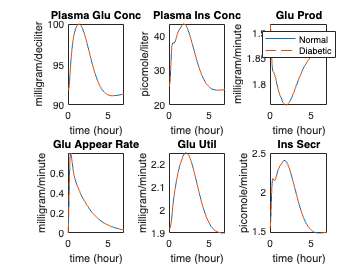

outputNames = {'Plasma Glu Conc', 'Plasma Ins Conc', 'Glu Prod', ...
    'Glu Appear Rate', 'Glu Util', 'Ins Secr'};
figure;
for i = 1:numel(outputNames)
    subplot(2, 3, i);

    [tNormal, yNormal  ]  = normalMealSim.selectbyname(outputNames{i});
    [tDiabetic, yDiabetic]  = diabeticMealSim.selectbyname(outputNames{i});
    
    plot( tNormal    , yNormal   , '-'       , ... 
          tDiabetic  , yDiabetic , '--'      );
  
    % Annotate figures 
    outputParam = sbioselect(m1, 'Name', outputNames{i});  
    title(outputNames{i});
    xlabel('time (hour)');
    if strcmp(outputParam.Type, 'parameter')
        ylabel(outputParam.ValueUnits);
    else
        ylabel(outputParam.InitialAmountUnits);
    end
    xlim([0 7]);
    
    % Add legend
    if i == 3
        legend({'Normal', 'Diabetic'}, 'Location', 'Best');
    end
    
end